对室内信道建模时通常认为是静态的或准静态的，常用2-径模型和指数模型

#### 2-径模型

两条射线：零时延直射路径、时延大于0的反射路径。其中平均过量时延和RMS时延相等。

#### 指数模型

信道平均功率随信道时延按指数规律递减：


$$P(\tau )=\frac{1}{\tau _d}e^{-\tau /\tau _d}$$


平均过量时延和RMS相等，为$\tau _d$

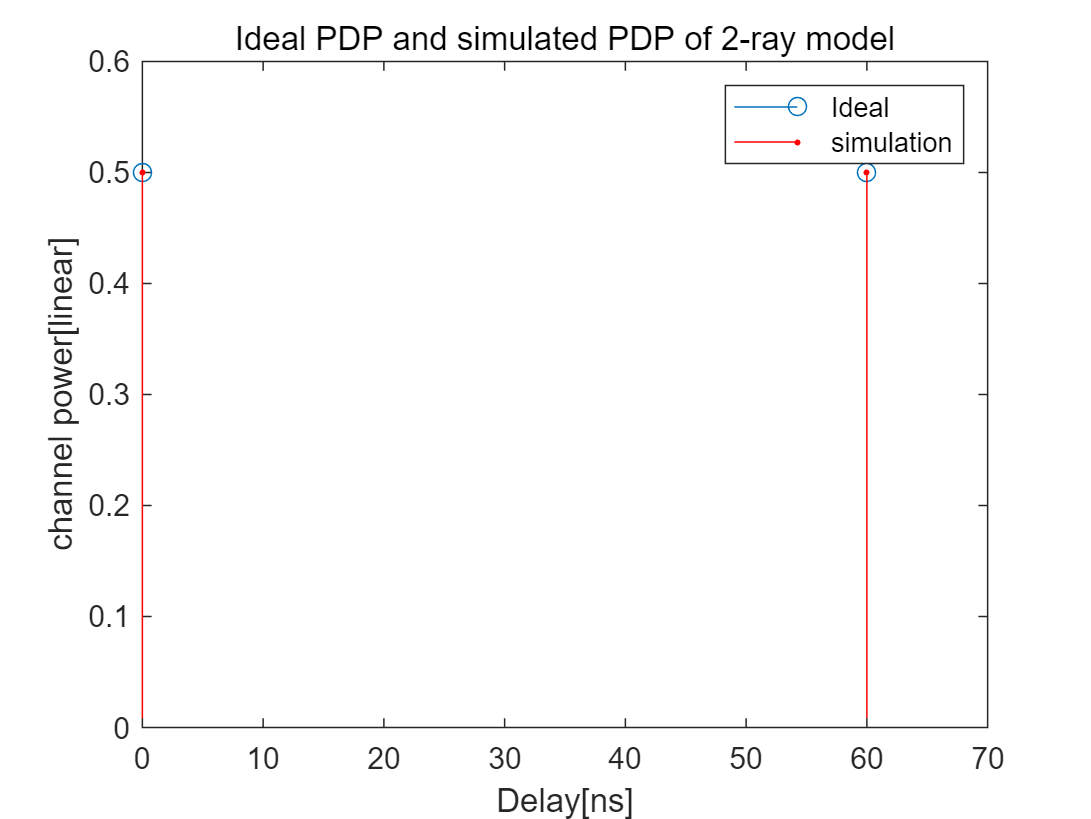

clear all;
clc;
scale = 1e-9;%ns
Ts = 10*scale;
t_rms = 30*scale;
num_ch = 10000;%信道数

%2-径模型
pow_2 = [0.5,0.5];
delay_2 = [0 t_rms*2]/scale;
H_2 = Ray_model(num_ch).'*sqrt(pow_2);
avg_pow_h_2 = mean(H_2.*conj(H_2));
figure()
stem(delay_2,pow_2)
hold on;
stem(delay_2,avg_pow_h_2,'r.')
xlabel('Delay[ns]')
ylabel('channel power[linear]')
title('Ideal PDP and simulated PDP of 2-ray model');
legend('Ideal','simulation')

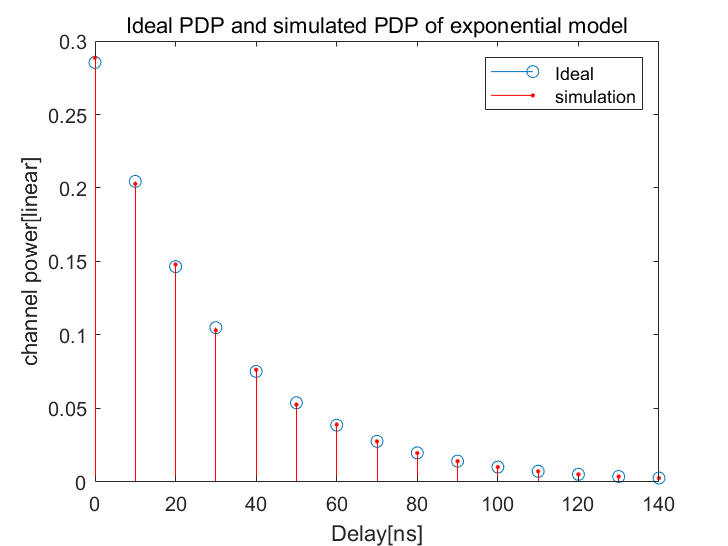


% 指数模型
pow_e = exp_PDP(t_rms,Ts);
delay_e = (0:length(pow_e)-1)*Ts/scale;
for i=1:length(pow_e)
    H_e(:,i) = Ray_model(num_ch).'*sqrt(pow_e(i));
end
avg_pow_h_e = mean(H_e.*conj(H_e));
figure()
stem(delay_e,pow_e);
hold on;
stem(delay_e,avg_pow_h_e,'r.')
xlabel('Delay[ns]')
ylabel('channel power[linear]')
title('Ideal PDP and simulated PDP of exponential model');
legend('Ideal','simulation')

function H=Ray_model(L)
    %输入：
    %       L:信道实现数
    % 输出：
    %         H：信道向量
    H = (randn(1,L)+1j*randn(1,L))/sqrt(2);
end
function PDP=exp_PDP(tau_d,Ts,A_dB,norm_flag)
%     输入：
%         tau_d：RMS时延扩展
%         Ts:     采样周期
%         A_dB:   最小不可忽略功率
%         norm_flag:归一化功率为1
%     输出：
%         PDP:    PDP向量
    if nargin < 4
        norm_flag = 1;
    end
    if nargin <3 
        A_dB = -20;
    end
    sigma_tau = tau_d;
    A = 10^(A_dB/10);
    lmax = ceil(-tau_d*log(A)/Ts);
    if norm_flag
        p0 = (1-exp(-Ts/sigma_tau))/(1-exp(-(lmax+1)*Ts/sigma_tau));
    else
        p0 = 1/sigma_tau;
    end

    l=0:lmax;
    PDP = p0*exp(-l*Ts/sigma_tau);
end
